# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder, any output images you might have saved and this livescript file.

Since we need to access the functions and data folder the first step is to add these two locations to MATLAB's path.

addpath('./functions');
addpath('./data');
addpath('./failure_cases');

**Important rules:** You are only allowed to ask TAs and lectures for help. It is not allowed to copy solutions, not even partially, from other sources (your fellow students, internet, Large Language Models or whatever).

# Lab 2: Learning and convolutional neural networks

## 2.1 Learning a Linear Classifier

In this part, we will try to learn a linear classifier for blood cell detection. Note that the classifier could also be viewed as a minimal neural network consisting of three parts: a scalar product node (or fully-connected node), a constant (or bias) term and a logistic sigmoid function. To find good parameters we will try to minimize the negative log-likelihood over a small training set.

The output from our classifier is a probability p for the input patch being centered at a cell centre. The sigmoid function will make sure that 0 ≤ p ≤ 1. To be more precise the output is


$$p=\frac{e^y }{1+e^y }\;\;\;\;\textrm{where}\;\;\;\;y=I\cdot \omega +\omega_0$$


Instead of testing a bunch of manually chosen w’s and w_0’s, we will try to learn good values for all the parameters. This requires training examples, that you find in cell_data.mat.

## Ex 2.1 

## Load the data using

load cell_data.mat

It loads a structure, cell_data, with two fields, `fg_patches` and `bg_patches`, corresponding to positive (centered blood cells) negative examples respectively.

## Ex 2.2 

Create two new variables, examples and labels. The variable examples should be a cell structure containing all the patches (both positives and negatives) and labels should be an array with the same number of elements such that `labels(i) = 1` if` examples{i}` is a positive example, and `labels(i) = 0` otherwise.

fg_length = length(cell_data.fg_patches);
bg_length = length(cell_data.bg_patches);
tot_length = fg_length + bg_length;     % Total amount of patches

examples = cell(1, (tot_length));
labels = zeros(1, (tot_length));

% Add foreground patches
for i = 1:fg_length
    examples(i) = cell_data.fg_patches(i);
    labels(i) = 1;
end 

% Add background patches
for i = 1:bg_length
    examples(fg_length + i) = cell_data.bg_patches(i);
    labels(fg_length + i) = 0;
end

## Ex 2.3

Split the data into training,` (examples_train, labels_train)`, and validation,` (examples_val, labels_val)`. The two should have a similar structure to examples and labels. Write on the report which percentage of the data you used for validation. Also, the splitting of the data into the two sets should be done in a random manner, for example, using randperm. 

**Percentage of data used for training**: 90 %

**Percentage of data used for validation**: 10 %

val_ratio = 0.1;    % Percentage of data used for validation

train_length = round(tot_length * (1 - val_ratio));    % Number of training examples
val_length = round(tot_length * val_ratio);        % Number of validation examples

shuffled_indices= randperm(tot_length);

% Extract training patches
examples_train = cell(1, train_length);
labels_train = zeros(1, train_length);
for i = 1:train_length
    index = shuffled_indices(i);
    examples_train(i) = examples(index);
    labels_train(i) = labels(index);
end

% Extract validation patches
examples_val = cell(1, val_length);
labels_val = zeros(1, val_length);
for i = 1:val_length
    index = shuffled_indices(i);
    examples_val(i) = examples(index);
    labels_val(i) = labels(index);
end

## 2.2 Training the classifier

We will try to find parameters that minimize the negative log-likelihood on the training data. More precisely,


$$L\left(\theta \right)=\sum_{i\in S_+ } -\ln \left(p_i \right)+\sum_{i\in S_- } -\ln \left(1-p_i \right)=\sum_i L_i \left(\theta \right)$$


where $p_i$ refers to the classifier output for the ith training example. As in the lectures we will refer to the terms here as the partial loss $L_i$.

Before doing the next exercise, you need to work out how to compute the gradient of the partial loss $L_i$.

## Ex 2.4

Make a function

        `[wgrad, w0grad] = partial_gradient(w, w0, example_train, label_train)`

that computes the derivatives of the partial loss L_i with respect to each of the classifier parameters. Let the output wgrad be an array of the same size as the weight image, w (and let w0grad be a number). 

% [wgrad, w0grad] = partial_gradient(0.01 * randn(35,35), 0, examples_train{1,1}, labels_train(1));

At each iteration of stochastic gradient descent, a training example, i, is chosen at random. For this example the gradient of the partial loss, L_i , is computed and the parameters are updated according to this gradient. The most common way to introduce the randomness is to make a random reordering of the data and then going through it in the new order. One pass through the data is called an epoch.

## Ex 2.5

Make a function

        `[w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train)`

that performs one epoch of stochastic gradient descent

% [w, w0] = process_epoch(1, 1, 1, examples_train, labels_train)

## Ex 2.6 

Initialize `w = s * randn(35,35);`, with `s = 0.01` and `w0 = 0;` and run 5 epochs on your training examples. Plot w after each epoch (or after each iteration if you are curious), to get a sense of what is happening. Also, try using different `s={10,1,0.1,0.01}` and plot w after 5 epochs for each value of s. Include on the report visualizations of w for the different values of s, along with an written explanation of what is happening.

s = 10


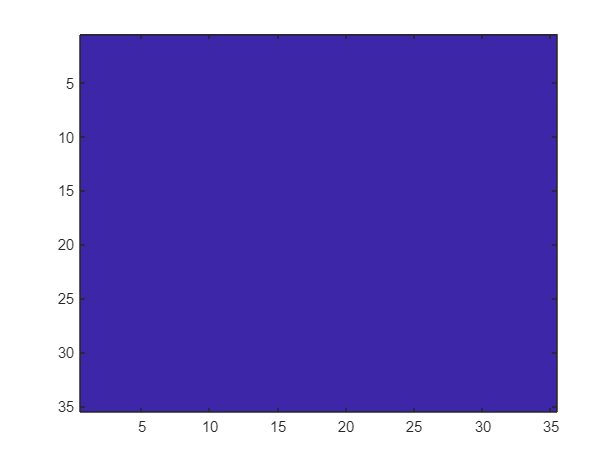

s = 1


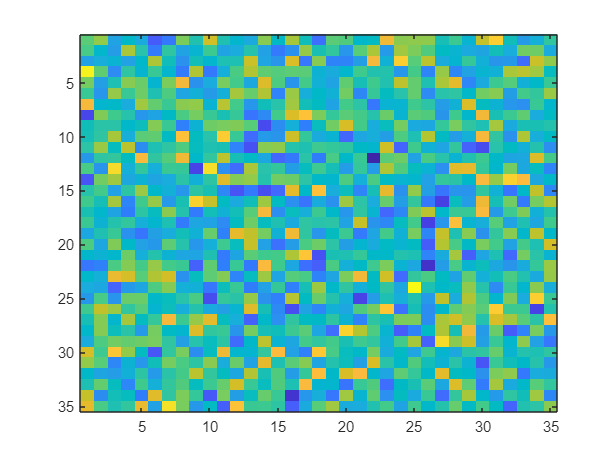

s = 0.1


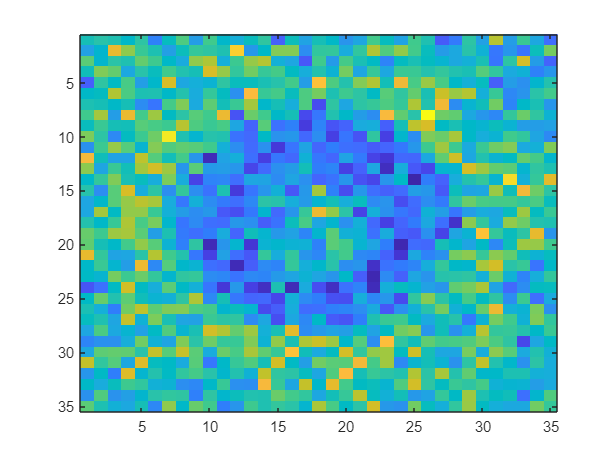

s = 0.01


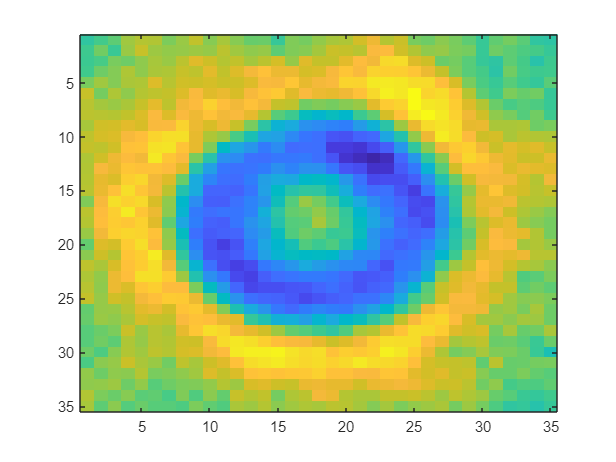

lrate = 0.01;   % Is this OK?

for i = 1:4
    s = [10,1,0.1,0.01];

    % Initialize parameters
    w = s(i) * randn(35,35);
    w0 = 0;

    % Run 5 epochs
    for j = 1:5
        [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train);
    end
    disp(['s = ', num2str(s(i))])
    figure; imagesc(w);
end

**Your written answer here:**

When s is large, the initial weights in the w-matrix are large. This results in large values for y = w * x + w0, which causes the exponents in the sigmoid function to explode towards infinity and cause a numerical error. TODO: explain more

## Exercise 2.7

As said before, at each iteration of stochastic gradient descent, a training example is chosen at random. Check what happens to w after 5 epochs when that training example is not chosen randomly but in sequence, i.e. first `i = 1`, then `i = 2`, and so on. Include on the report a visualization of w for this case. (Don’t forget to change back your function to a random choice of i after this exercise).

You can display the resulting filters inside this livescript notebook using the function imagesc.

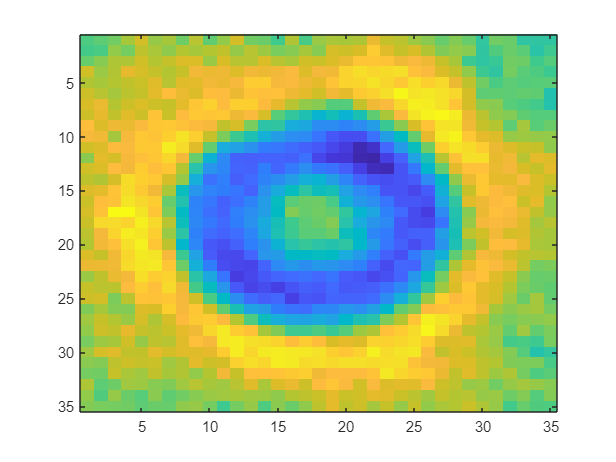

lrate = 0.01;
s = 0.01;

% Shuffled
w = s * randn(35,35);   % Initialize parameters
w0 = 0;
for j = 1:5
    [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train);
end
figure; imagesc(w);

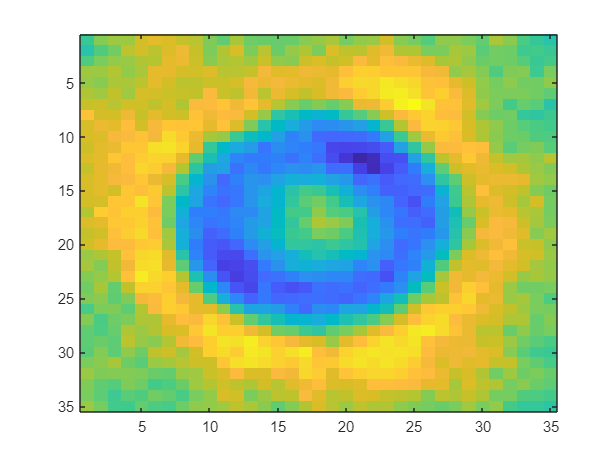

% Not shuffled
w = s * randn(35,35);   % Initialize parameters
w0 = 0;
for j = 1:5
    [w, w0] = process_epoch_not_shuffled(w, w0, lrate, examples_train, labels_train);
end
figure; imagesc(w);

## Ex 2.8 

Make a function

        `predicted_labels = classify(examples_val,w,w0);`

that applies the classifier to the example data. After that, use it on `examples_train` and examples_val and check how much accuracy it gets for each by comparing the predicted labels with `labels_train` and `labels_val` respectively. Write on your report the highest accuracy you were able to achieve in the training and validation data. Hint: train the classifier for longer than 5 epochs to make sure that it converges.

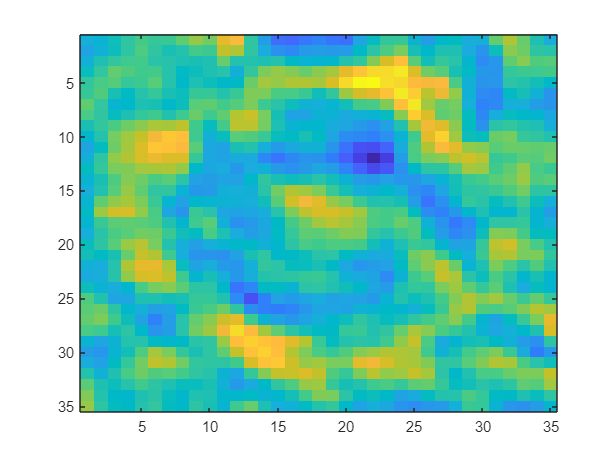

% Train the classifier
lrate = 0.01;
s = 0.01;

w = s * randn(35,35);
w0 = 0;

for j = 1:800
    [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train);
end
figure; imagesc(w);

When you have defined the function run the following code.

% Training examples
predicted_labels_train = classify(examples_train,w,w0);
correct = sum(predicted_labels_train==labels_train);
accuracy_train = 100*correct/length(labels_train);

% Validation examples
predicted_labels_val = classify(examples_val,w,w0);
correct = sum(predicted_labels_val==labels_val);
accuracy_val = 100*correct/length(labels_val);

fprintf(("Training Accuracy: ")+accuracy_train+("%%"))

Training Accuracy: 99.1667%

fprintf(("Validation Accuracy: ")+accuracy_val+("%%"))

Validation Accuracy: 100%

**Write the highest accuracy you were able to get here:**

Highest training accuracy: 100 %

Highest validation accuracy: 100 %

## Ex 2.9

The data for training this classifier consists on only 400 examples (less if you consider that you have split it into training and validation). To achieve higher accuracy it might be useful to perform some data augmentation before the training. In this exercise you will increase the number of elements in the training examples by M times. Make a function

        `[examples_train_aug,labels_train_aug] = augment_data(examples_train,labels_train,M)`

that takes each sample of the original training data and applies M random rotations (you can use Matlab function imrotate), from which result M new examples. Store these new examples in examples_train_aug and their corresponding labels in labels_train_aug. Train the classifier with this augmented data and write on your report the new values for accuracy on the training and validation examples.

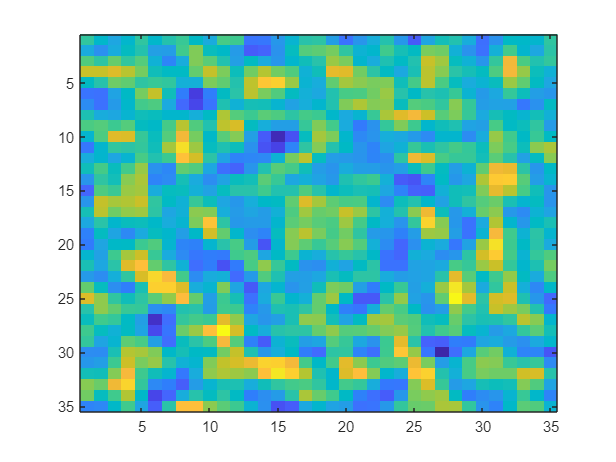

M = 3;  % Number of times original data is augmented
[examples_train_aug,labels_train_aug] = augment_data(examples_train,labels_train,M);

% Train the classifier
lrate = 0.01;
s = 0.01;

w = s * randn(35,35);
w0 = 0;

for j = 1:10000
    [w, w0] = process_epoch(w, w0, lrate, examples_train_aug, labels_train_aug);
end
figure; imagesc(w);

% Training examples
predicted_labels_train = classify(examples_train_aug,w,w0);
correct = sum(predicted_labels_train==labels_train_aug);
accuracy_train = 100*correct/length(labels_train_aug);

% Validation examples
predicted_labels_val = classify(examples_val,w,w0);
correct = sum(predicted_labels_val==labels_val);
accuracy_val = 100*correct/length(labels_val);

fprintf(("Training Accuracy: ")+accuracy_train+("%%"))

Training Accuracy: 100%

fprintf(("Validation Accuracy: ")+accuracy_val+("%%"))

Validation Accuracy: 97.5%

**Write the highest accuracy you were able to get here:**

Highest training accuracy: 100 %

Highest validation accuracy: 100 %

## 2.3 Convolutional neural networks

In the last part, your task is to train convolutional neural networks using Matlab.

## `Ex 2.10 `

Run the following cell

[imgs, labels] = digitTrain4DArrayData;

to load a dataset of images of digits into Matlab. (Make sure you have the Deep Learning toolbox installed). You will find the 5000 digit images in imgs. Plot a few of them to see what the data looks like.

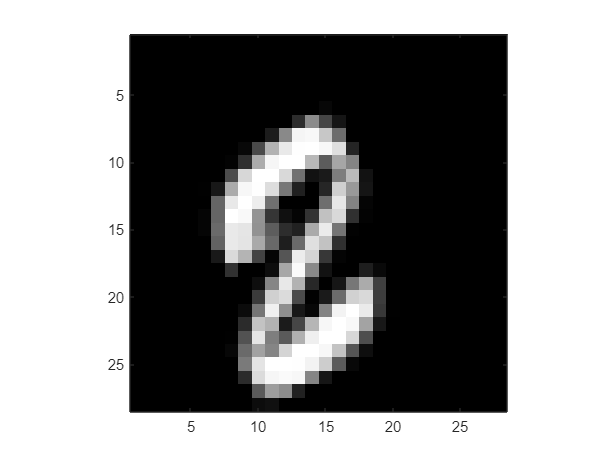

N = 3211; % We have 5000 images so any number between 1 and 5000 works.
img = imgs(:,:,:,N);
imagesc(img), axis image, colormap gray

The next step is to define a network for classification. In Matlab, you do this by simply giving an array of the layers. For example, this would be a linear classifier similar to the one you trained for cells:

        layers = [

            imageInputLayer([35 35 1]);

            fullyConnectedLayer(1);

            softmaxLayer();

            classificationLayer()];

## Ex 2.11 

Make a function

        `layers = basic_cnn_classifier()`

that implements the following network in Matlab:

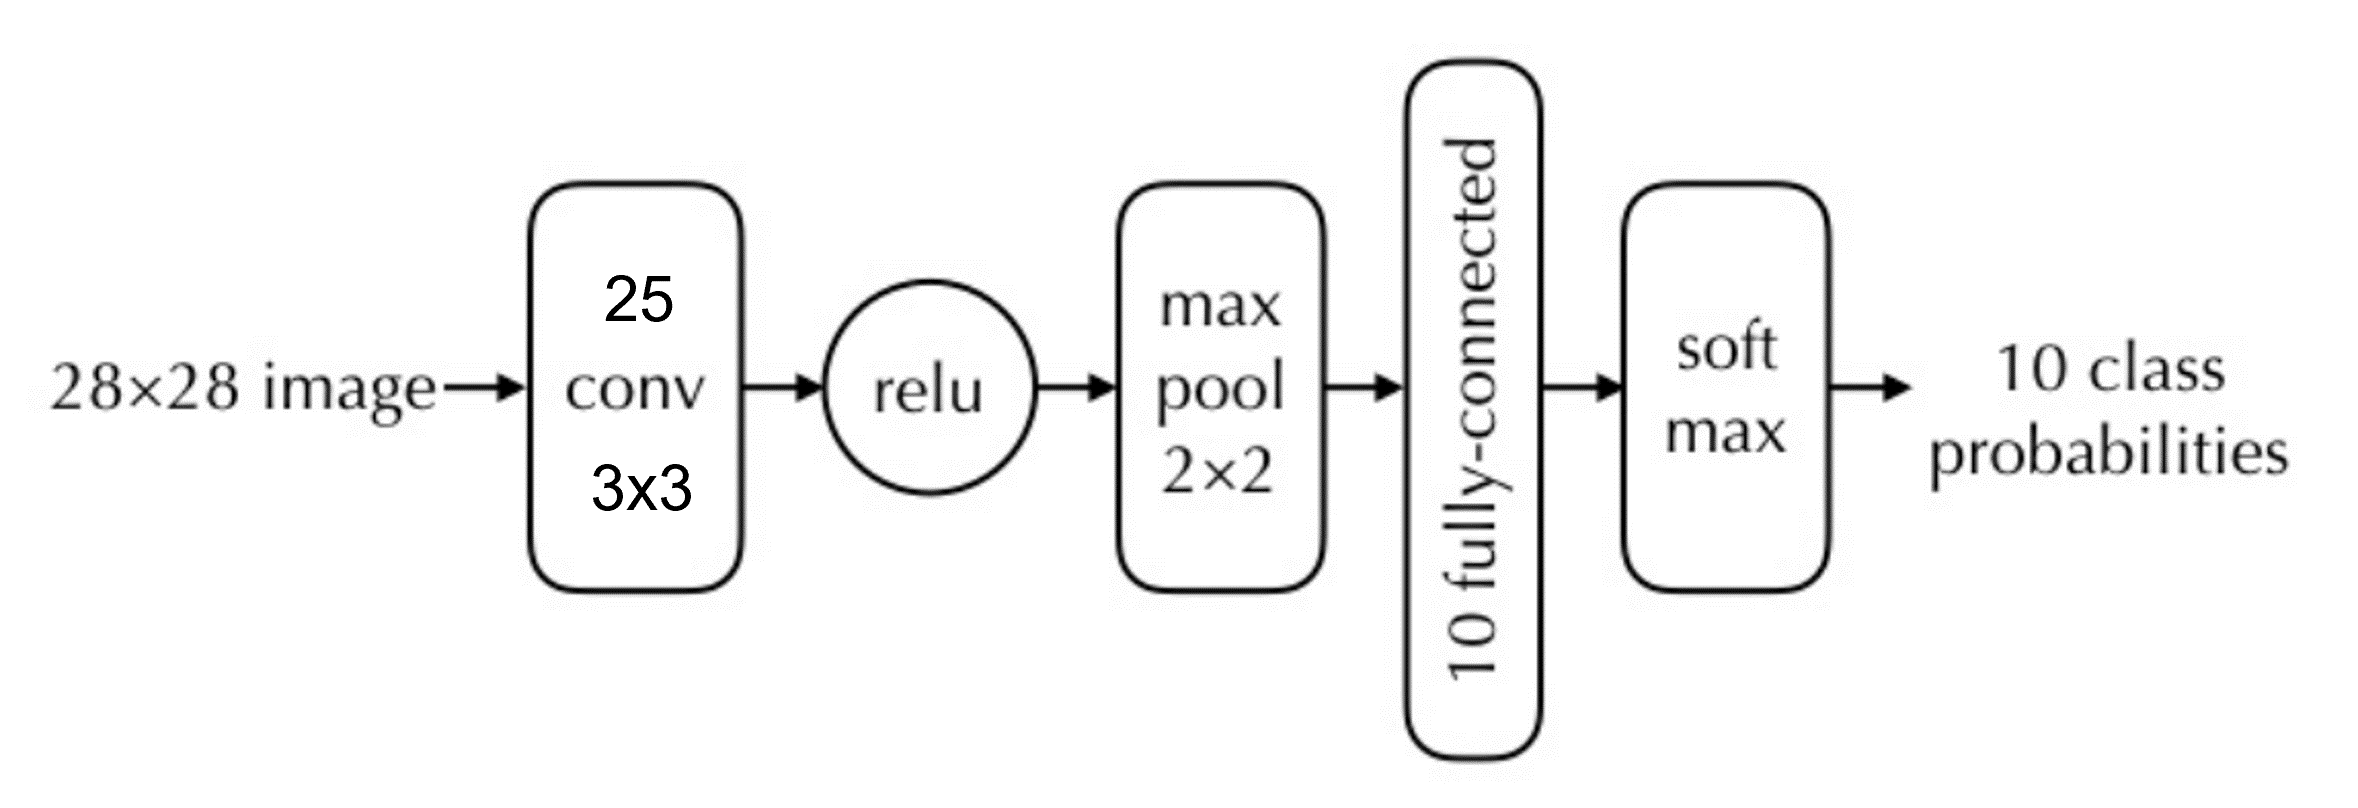

Apart from the layers above the functions `convolution2dLayer`, `reluLayer` and `maxPooling2dLayer` will be useful. Note that you have to set the *stride* for max pooling to 2 to get the expected downsampling.

When you have written the function run the following cell:

layers = basic_cnn_classifier()

layers =   7×1 Layer array with layers:

     1   ''   Image Input             28×28×1 images with 'zerocenter' normalization
     2   ''   2-D Convolution         25 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Fully Connected         10 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

## Ex 2.12 

Create a set of training options telling Matlab to use stochastic gradient descent with momentum (SGDM), for the optimization:

        `options = trainingOptions('sgdm');`

Now train the network (using default parameters) by running

        net = trainNetwork(imgs, labels, layers, options)

options = trainingOptions('sgdm');
net = trainNetwork(imgs, labels, layers, options)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        7.03% |       2.3123 |          0.0100 |
|       2 |          50 |       00:00:01 |       44.53% |       1.8538 |          0.0100 |
|       3 |         100 |       00:00:02 |       55.47% |       1.4047 |          0.0100 |
|       4 |         150 |       00:00:03 |       60.16% |       1.1885 |          0.0100 |
|       6 |         200 |       00:00:04 |       66.41% |       1.0726 |          0.0100 |
|       7 |         250 |       00:00:05 |       67.97% |       1.0003 |          0.0100 |
|       8 |         300 |  

net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


## Ex 2.13 

Try the network on a few of the training images. You can use `net.predict(img)` to get the ten output probabilities or `net.classify(img)` to get the most probable class.

net.predict(img)

ans = 1×10 single row vector
    0.0124    0.0457    0.6189    0.0009    0.0089    0.0009    0.2657    0.0018    0.0015    0.0433


net.classify(img)

ans = categorical
     2 


## Ex 2.14 

Work out how many trainable parameters your network contains. Include the answer in your submission. If you explore what the data structure net actually contains, you can find the answer there as well. Note that the convolution layer does not use padding so the output from the convolution layer is smaller than the input.

**Write your answer here:**

The 3x3 convolutional layer has 9 weights + 1 bias term per layer. Since there is 25 layers, there is a total of 250 parameters here.

The fully-connected layer has 13 * 13 * 25 weights + 1 bias term per neuron. Since there is 10 classes, there is a total of 42 260 parameters here.

There are no trainable parameters in the ReLu, max pooling or softmax layers.

This gives a total of **42 510 trainable parameters** in the network as a whole.

## Ex 2.15 

Matlab prints a lot of output, for example the accuracy on the training set. Recall from the lectures that this number is not very good for judging the quality of a classifier. Instead we should save a subset of the data as a validation set, that we can use to evaluate the trained network. 

Divide the data into training `imgs` and `labels` into new variables `imgs_train, labels_train, imgs_val, labels_val`.

val_ratio = 0.1;    % Percentage of data used for validation
tot_length = length(imgs);

train_length = round(tot_length * (1 - val_ratio));    % Number of training examples
val_length = round(tot_length * val_ratio);        % Number of validation examples

% Extract training images
imgs_train = imgs(:,:,:,1:train_length);
labels_train = labels(1:train_length);

% Extract validation images
imgs_val = imgs(:,:,:,train_length + 1:tot_length);
labels_val = labels(train_length + 1:tot_length);

Make a function 

        `net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val) `

that runs a few epochs of training and then evaluates the accuracy on the validation set. In this case, Matlab has given us a separate test set, so we don’t have to save images for that purpose. *Matlab hints:* You can run multiple images at once by stacking them along the fourth dimension. If you want to continue training the same network you can run

        `net = train_classifier(net.Layers, imgs_train, labels_train, imgs_val, labels_val)`

net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       14.06% |       2.2990 |          0.0100 |
|       2 |          50 |       00:00:00 |       48.44% |       1.7918 |          0.0100 |
|       3 |         100 |       00:00:01 |       53.12% |       1.3928 |          0.0100 |
|       5 |         150 |       00:00:02 |       66.41% |       1.0867 |          0.0100 |
|       6 |         200 |       00:00:03 |       60.94% |       1.0811 |          0.0100 |
|       8 |         250 |       00:00:04 |       69.53% |       0.8675 |          0.0100 |
|       9 |         300 |  

**Ex 2.16 **

To run a convolutional neural network we have to perform a massive amount of computations. Hence it is very important to consider the computational load when designing a network. For the network below, compare (roughly) the time consumption of the blue and the red layers. You can ignore effects of padding. Include your answer and your motivation in your submission.

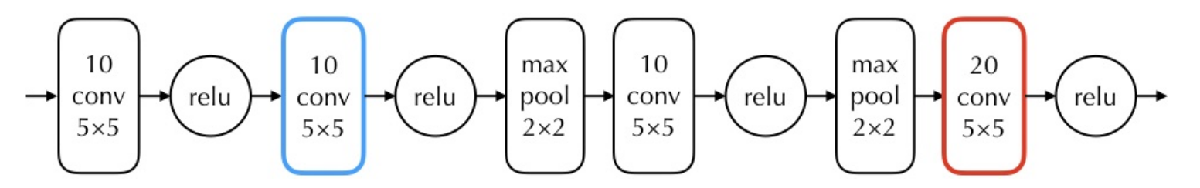

**Write your answer here:**

We assume an input image size of NxN and no effects of padding.

**Blue** is a N*N*10 convolution layer that has a 5x5 filter that operates on 10 channels. It requires 5*5*10 = 250 multiplications to calculate the value of each voxel in this layer. Since the layer has N*N*10 = 10*N^2 voxels, a total of **2500*N^2 multiplications** has to be done to compute the blue layer.

**Red **is a N/4*N/4*20 convolution layer (N/4 is becuase of the two max pooling layers) that has a 5x5 filter that operates on 10 channels. It requires 5*5*10 = 250 multiplications to calculate the value of each voxel in this layer. Since the layer has N/4*N/4*20 = 1.25*N^2 voxels, a total of **312.5*N^2 multiplications** has to be done to compute the red layer.

Blue has 8x the number of multiplications compared to red. If we assume that the multiplications is the most time consuming part, blue should take rougly 8 times longer to compute than red.

## Ex 2.17

Replace the blue box of the network in the figure above by a sequence of two layers of 10 3 × 3 convolutional filters. What changes in terms of network parameters, time consumption and accuracy? Again, you are not supposed to implement the network.

**Write your answer here:**

Each of the new convolutional layers have a 3x3 filter that operates on 10 channels. It requires 3*3*10 = 90 muliplications to calculate tha value of each voxel in this layer. Since the layer has N*N*10 = 10*N^2 voxels, a total of 900*N^2 multiplications is done for each layer. For the two layers, a total of **1800*N^2 multiplications** take place. The new layer should take roughly 72 % the time of the old blue layer.

The old blue layer had 5*5 filter weights + 1 bias term for each filter. 10 filters gives a total of 260 parameters. The new layer have 3*3 filter weights + 1 bias term for each filter. 20 filters (10 for each layer) gives a total of 200 parameters.

The old layer with more parameters should on average be more accurate. The new layer is however faster to compute.

## Ex. 2.18

Make a copy of basic_cnn_classifier.m and name it better_cnn_classifier.m. Try modifying the network by adding more layers. Also experiment with the training options. How much can you improve the results?

layers_better = better_cnn_classifier();
options = trainingOptions('sgdm', MaxEpochs=20, InitialLearnRate=0.1);
net_better = trainNetwork(imgs, labels, layers, options)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       11.72% |       2.2961 |          0.1000 |
|       2 |          50 |       00:00:01 |       71.09% |       0.7689 |          0.1000 |
|       3 |         100 |       00:00:02 |       85.94% |       0.4247 |          0.1000 |
|       4 |         150 |       00:00:03 |       91.41% |       0.2159 |          0.1000 |
|       6 |         200 |       00:00:04 |       99.22% |       0.0640 |          0.1000 |
|       7 |         250 |       00:00:05 |      100.00% |       0.0400 |          0.1000 |
|       8 |         300 |  

net_better =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


## Ex 2.19 

Load the builtin test images using

        `[imgs_test, labels_test] = digitTest4DArrayData;`

Run the network on all the test images. You apply the network to an image using

        pred = net.classify(image)

Compute precision and recall for each of the 10 classes and include these in your submission. The definitions of precision and recall can be found in the lecture notes chapter 4.

[imgs_test, labels_test] = digitTest4DArrayData;    % Load test images

test_length = length(imgs_test);    % Number of test images

% Classify all test images
predicted_labels = categorical(zeros(test_length, 1));
for i = 1:test_length
    predicted_labels(i, 1) = net_better.classify(imgs_test(:,:,:,i));
end

num_pred = zeros(10, 1);
num_correct_pred = zeros(10, 1);
num_examples = zeros(10, 1);

failure_cases = 20;  % Number of failures to save

% Calculate the numer of correct classifications, total number of
% classifications and the actual correct number of labels.
for i = 1:test_length
    pred = predicted_labels(i);
    correct = labels_test(i);

    num_pred(pred) = num_pred(pred) + 1;
    num_examples(correct) = num_examples(correct) + 1;

    if pred == correct  % If correctly classified
        num_correct_pred(pred) = num_correct_pred(pred) + 1;
    elseif failure_cases > 0    % Wrongly classified and saves left
        file_path = 'failure_cases/'+string(correct)+'_mistaken_as_'+string(pred)+'.png';
        imwrite(imgs_test(:,:,:,i),file_path);
        failure_cases = failure_cases - 1;
    end
end

% precision for class A = number of examples correctly classified as A /
% number of examples classified as class A (4.2)
precision = num_correct_pred ./ num_pred;

% recall for class A = number of examples correctly classified as A /
% number of examples from class A 
recall = num_correct_pred ./ num_examples;

for i = 1:10
    fprintf(i+(": precision ")+round(precision(i)*100, 1)+(" %%")+ ...
        (", recall ")+round(recall(i)*100, 1)+(" %%\n"))
end

1: precision 99.4 %, recall 99.2 %
2: precision 98.6 %, recall 99 %
3: precision 98.6 %, recall 98.6 %
4: precision 97.3 %, recall 99.2 %
5: precision 99.2 %, recall 96.6 %
6: precision 98 %, recall 96.6 %
7: precision 97 %, recall 98.2 %
8: precision 98 %, recall 99.4 %
9: precision 100 %, recall 99.6 %
10: precision 99.4 %, recall 99 %


## Ex 2.20

Save three of the failure cases with names indicating what digit they were mistaken for. Include these in your submission. You can use imwrite(img, ’mistaken_as_5.png’) to save an image if it is correctly scaled. Have a look at the file before submitting it, so it looks right.

You can load and display the images here using imagesc:

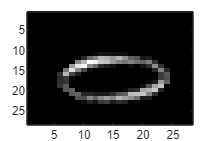

imagesc(imread('failure_cases/0_mistaken_as_1.png'))

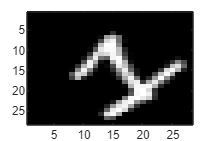

imagesc(imread('failure_cases/1_mistaken_as_3.png'))

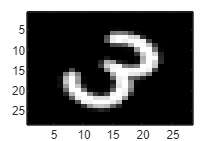

imagesc(imread('failure_cases/3_mistaken_as_2.png'))